# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Charlotte\ColorKb\BehavioralData'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Folder.Version     = ['C:\Users\User\Desktop\Charlotte\ColorKb\ProcessedBehavioralData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {21};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {31};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[42 43] [52 53] [62 63] [71 72]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [81 41 51 61];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {19};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {20};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 4. Analysis

#### General Set-Up

Deci.Analysis.Conditions    = mat2cell(CombVec([42 43],[52 53],[62 63],[71 72]),[4],[ones([1 16])]);
Deci.Analysis.CondTitle     = {'4 Change Yes Correct' '8 Change Yes Correct' '4 Nochange Yes Correct' '8 Nochange Yes Correct'...
    '4 Change No Correct' '8 Change No Correct' '4 Nochange No Correct' '8 Nochange No Correct' '4 Change Yest Incorrect'...
    '8 Change Yes Incorrect' '4 Nochange Yes Incorrect' '8 Nochange Yes Incorrect' '4 Change No Incorrect'...
    '8 Change No Incorrect' '4 Nochange No Incorrect' '8 Nochange No Incorrect'}; 

## 5. Plotting

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

%    1     2     3     4     5     6     7     8     9     10    11    12    13    14    15    16 
%  
%    1     1     0     0     0     0     1     1     1     1     0     0     0     0     1     1

%    42    43    42    43    42    43    42    43    42    43    42    43    42    43    42    43
%    52    52    53    53    52    52    53    53    52    52    53    53    52    52    53    53
%    62    62    62    62    63    63    63    63    62    62    62    62    63    63    63    63
%    71    71    71    71    71    71    71    71    72    72    72    72    72    72    72    72

Deci.Plot.Behv.Acc.Figure = [true true false false false false ];
Deci.Plot.Behv.Acc.Total = {{[1:16] [1:16]} {[1:2:16] [2:2:16]} {[1:2 5:6]} { [3:4 7:8]} {[9 10 13 14]} {[11 12 15 16]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1:8] [9:16]} {[1:2:8] [2:2:8]} {[5 6]} {[3 4]} {[13 14]} {[11 12]}};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' '4 8 percent' 'checking' 'checking'  'checking' 'checking'};
Deci.Plot.Behv.Acc.Subtitle = {{'Corr Percent' 'Inc Percent'} {'4 percent' '8 percent'} {'4yesmatyescor'} {'4nomatnocor'} {'8yesmatyescor'} {'8nomatnocor'}};

Deci.Plot.Behv.Acc.Block = [1:3];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = false;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  true;


Deci.Plot.Behv.RT.Figure = [true];
Deci.Plot.Behv.RT.Draw = {{[1:8] [9:16]}};
Deci.Plot.Behv.RT.Title = {'All Trials RT' };
Deci.Plot.Behv.RT.Subtitle = {{'Corr' 'Inc'}};
Deci.Plot.Behv.RT.Locks = [3 4];

Deci.Plot.Behv.RT.Block = [1:3];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = false;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'positional:nans';

** Extra**

Deci.Plot.Extra.List = false;
Deci.Plot.Extra.Functions = {'QL'};
Deci.Plot.Extra.Params = {{}};

Options

Deci.Run.Behavior = true;

## ** 6. Run**

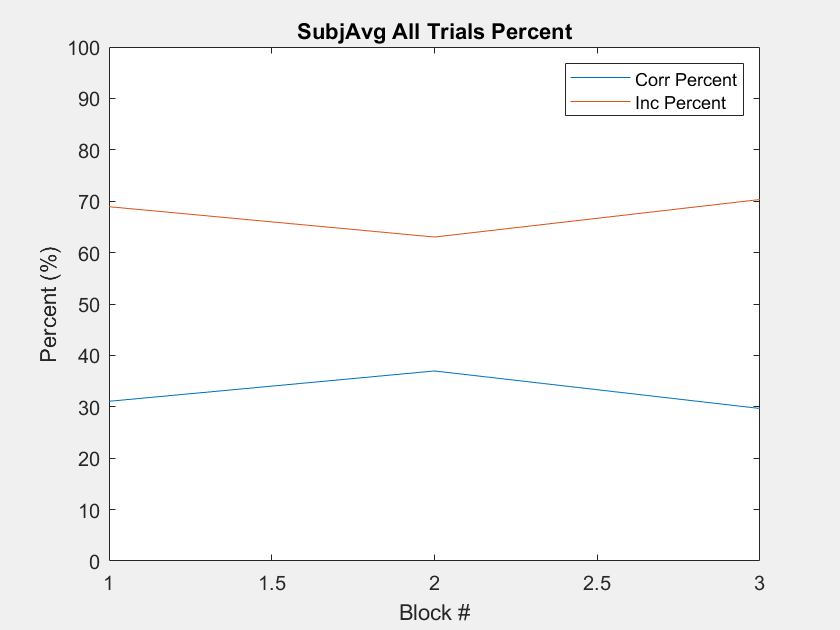

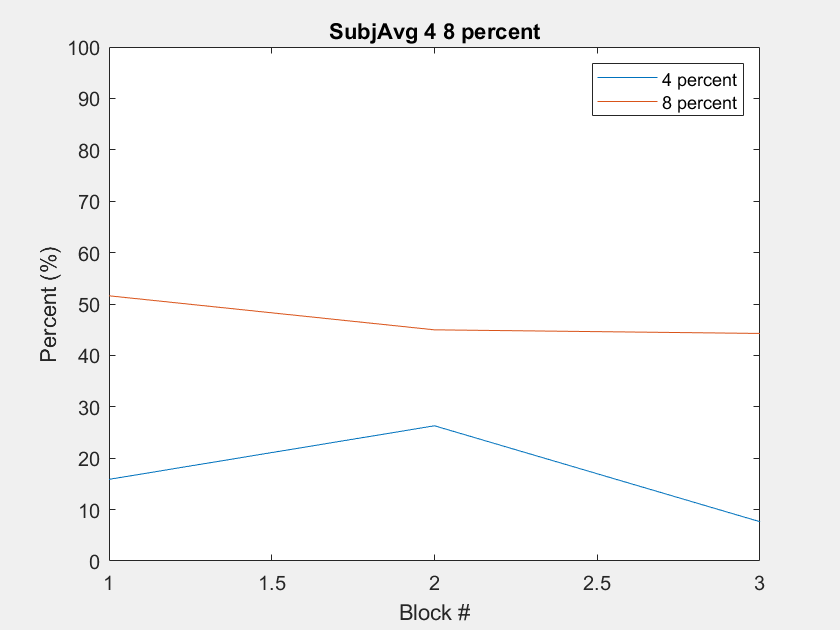

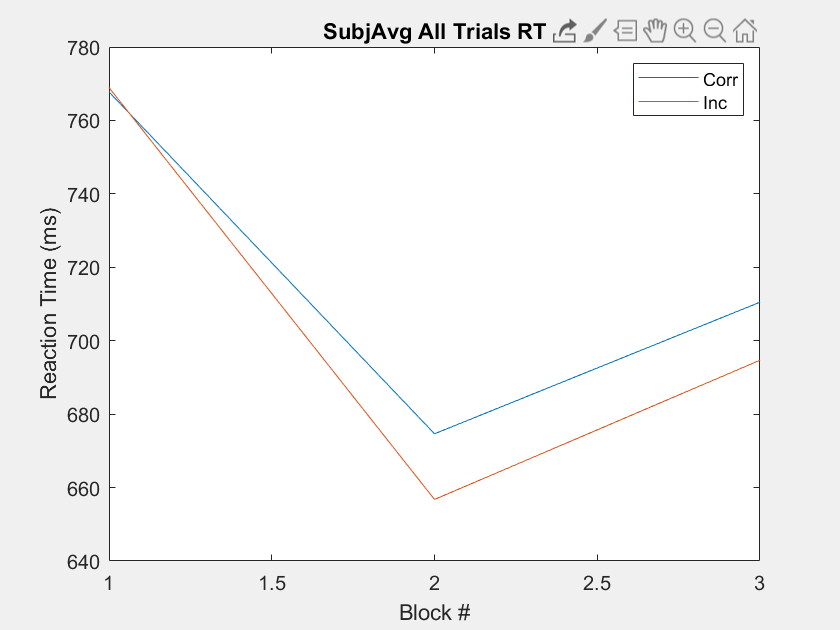

Deci_Backend(Deci);